# Poisson Flow Model of Cortical Folding Pattern

This MATLAB implementation provides the Poisson flow model for analyzing cortical folding patterns. The method represents cortical folding using signed mean curvature on a triangulated cortical surface and solves a screened Poisson equation directly on the surface. The resulting scalar potential and its surface gradient provide spatially regularized (or smoothed) representations of sulcal--gyral folding geometry. The screened Poisson equation is discretized using the finite-element method as


$$({\bf L}+\lambda{\bf A})u={\bf A}h,$$


where ${\bf L}$ is the stiffness matrix representing the Laplace--Beltrami operator, ${\bf A}$ is the finite-element mass matrix, $h$ is the signed mean curvature, and $u$ is the resulting Poisson folding potential we are estimating. The corresponding flow field is defined as $J=-\nabla u.$ The methodology and its application to juvenile myoclonic epilepsy (JME) are described in [1]

[1] Chung, M.K., Maccotta, L., Struck, A. 2026, [Poisson Flow of Cortical Folding in Juvenile Myoclonic Epilepsy](https://arxiv.org/pdf/2606.08404), arXiv:2606.08404.

Shorter conference version of the paper is available at:

[2] Chung, M.K., Maccotta, L., Struck, A. 2026 [Poisson Flow Model of Cortical Folding Pattern](https://github.com/laplcebeltrami/poisson/blob/main/chung.2026.EMBC.poisson.pdf), IEEE Engineering in Medicine and Biology Conference (EMBC), pages 1-5.

© 2026 Moo K. Chung

University of Wisconsin-Madison

## Reading pial surface 

The pial surface represents the outer cortical boundary and serves as the geometric domain for curvature estimation and the screened Poisson equation. Due to convoluted nature, cortical folding makes direct visualization difficult. Thus, corresponding inflated and flattened surfaces are also used. These surfaces preserve vertexwise correspondence with the pial surface, allowing quantities computed on the pial surface to be displayed without interpolation. Below, the left-hemisphere pial, inflated, and flat surfaces are shown as triangular meshes.

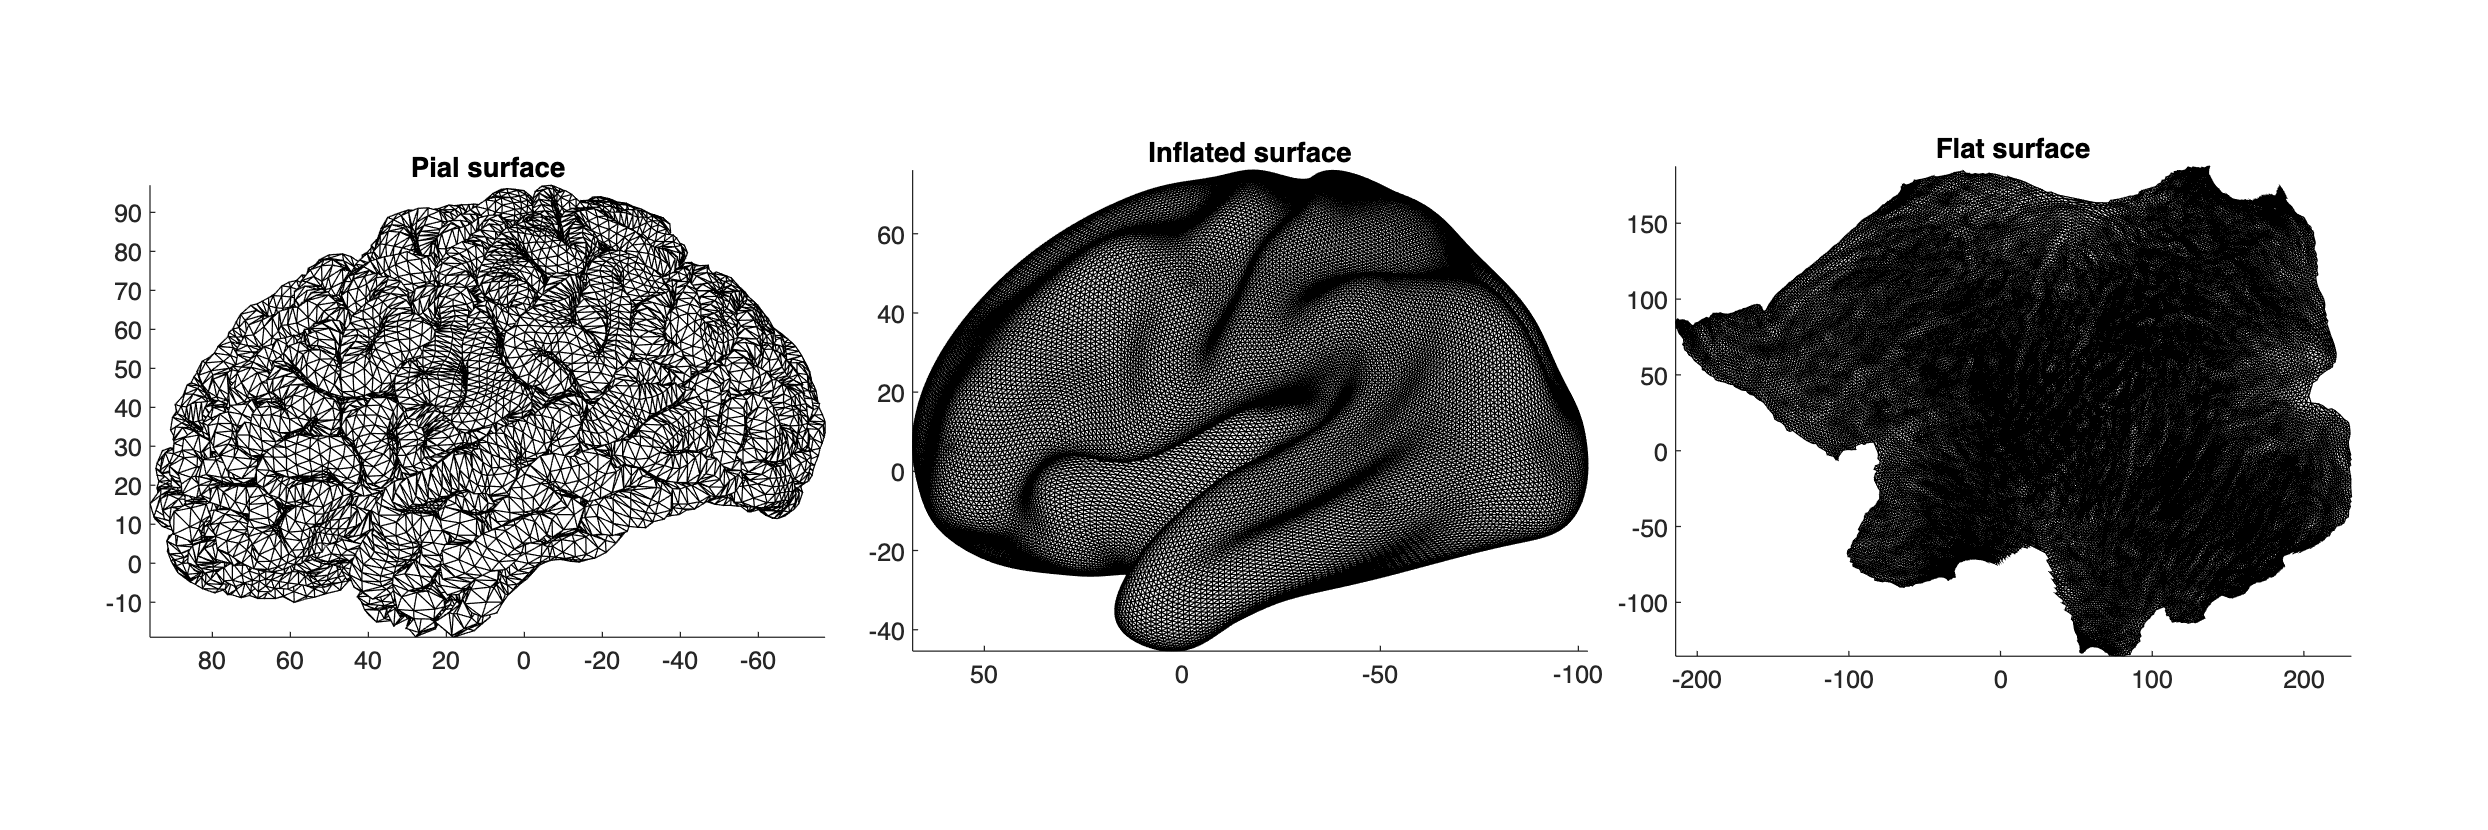

pialL = gifti('pial.surfL.gii'); 
inflatL = gifti('fs_LR.32k.L.inflated.surf.gii'); 
flatL = gifti('fs_LR.32k.L.flat.surf.gii'); 

figure('Position',[100 100 1800 600]); %This depends on your screen size
tiledlayout(1,3,'TileSpacing','compact','Padding','compact');

nexttile;
figure_wire(pialL); 
view([-90 0]); 
axis tight;
title('Pial surface');

nexttile;
figure_wire(inflatL); 
view([-90 0]); 
axis tight;
camlight;
title('Inflated surface');

nexttile;
figure_wire(flatL); 
axis tight;
title('Flat surface');

## Mean curvature estimation

Mean curvature is estimated using the local quadratic surface fitting method described in Chung et al. (2003). At each mesh vertex, a local coordinate system is constructed using neighboring vertices, and the cortical surface is approximated by a quadratic polynomial,


$$f(x_1,x_2)=\beta_1x_1+\beta_2x_2+\frac{1}{2}\beta_3x_1^2+\beta_4x_1x_2+\frac{1}{2}\beta_5x_2^2.$$


The fitted coefficients characterize the local first- and second-order surface geometry and are subsequently used to compute the mean curvature at each vertex. This produces a signed vertexwise curvature map representing local sulcal and gyral geometry.

Chung, M.K., Worsley, K.J., Robbins, S., Evans, A.C. 2003. [Tensor-based brain surface modeling and analysis](http://pages.stat.wisc.edu/~mchung/papers/CVPR/CVPR.pdf), CVPR, 467-473.

betaL       = surf2quadratic(pialL);
curvaturesL = surf2curvature(betaL);

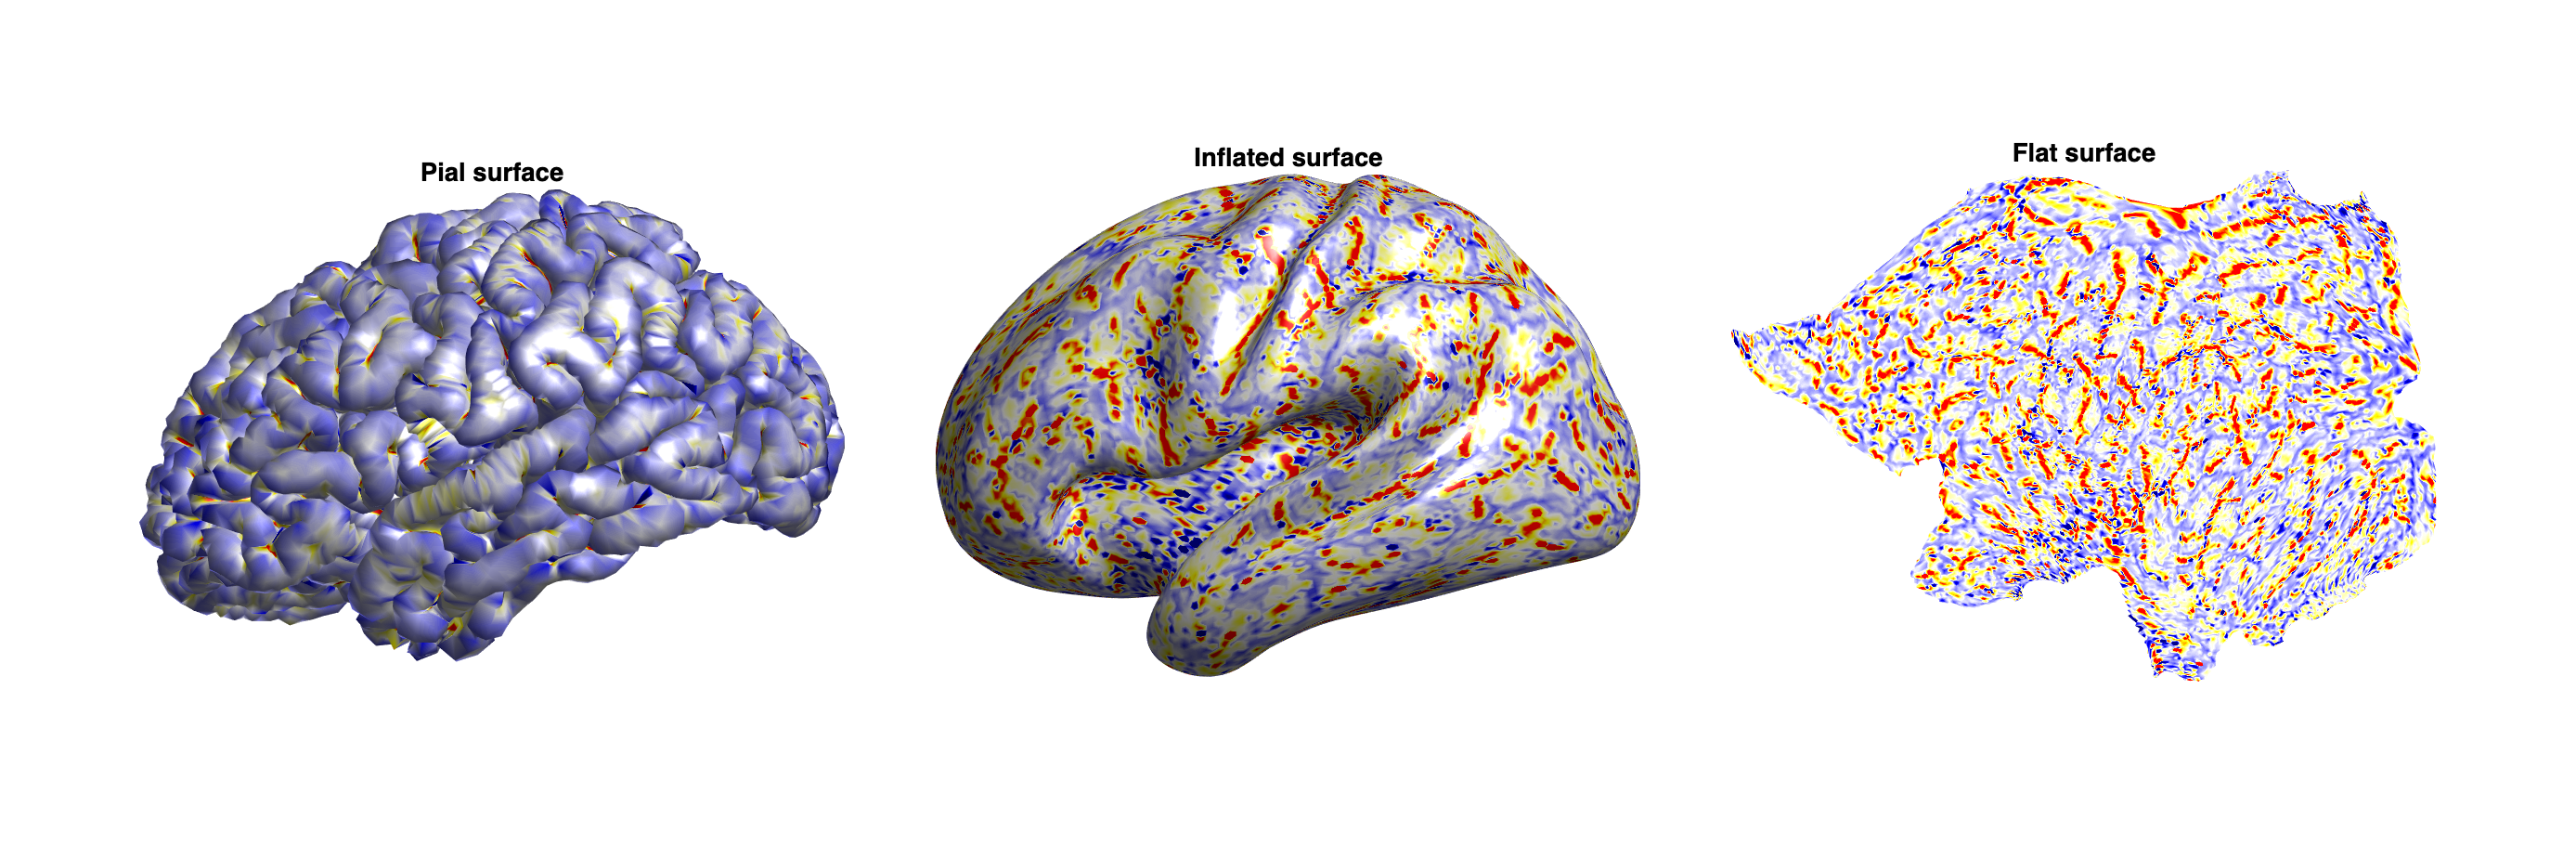

figure('Position',[100 100 1800 600]);
tiledlayout(1,3,'TileSpacing','compact','Padding','compact');

nexttile;
figure_trimesh(pialL, curvaturesL.mean, 'rywb');
view([-90 0]); clim([-0.5 0.5]); camlight;
title('Pial surface');

nexttile;
figure_trimesh(inflatL, curvaturesL.mean, 'rywb');
view([-90 0]); clim([-0.5 0.5]); camlight;
title('Inflated surface');

nexttile;
figure_trimesh(flatL, curvaturesL.mean, 'rywb');
clim([-0.5 0.5]); view(2);
title('Flat surface');

## Mean-centering 

The estimated mean-curvature field contains local geometric variation and high-frequency noise. Before applying the Poisson model, we subtract its area-weighted mean. For the standard Poisson equation


$$\mathcal{L}u=h,$$


on a closed cortical surface, a solution exists only when the forcing field satisfies the zero-mean condition


$$\int_{\mathcal{M}} h\,d\mu=0,$$


because the Laplace--Beltrami operator $\mathcal{L}$ has the constant functions in its null space,  i.e., $\Delta u = 0$ only if $u= const$. We therefore mean-center the curvature field with respect to cortical surface area. 

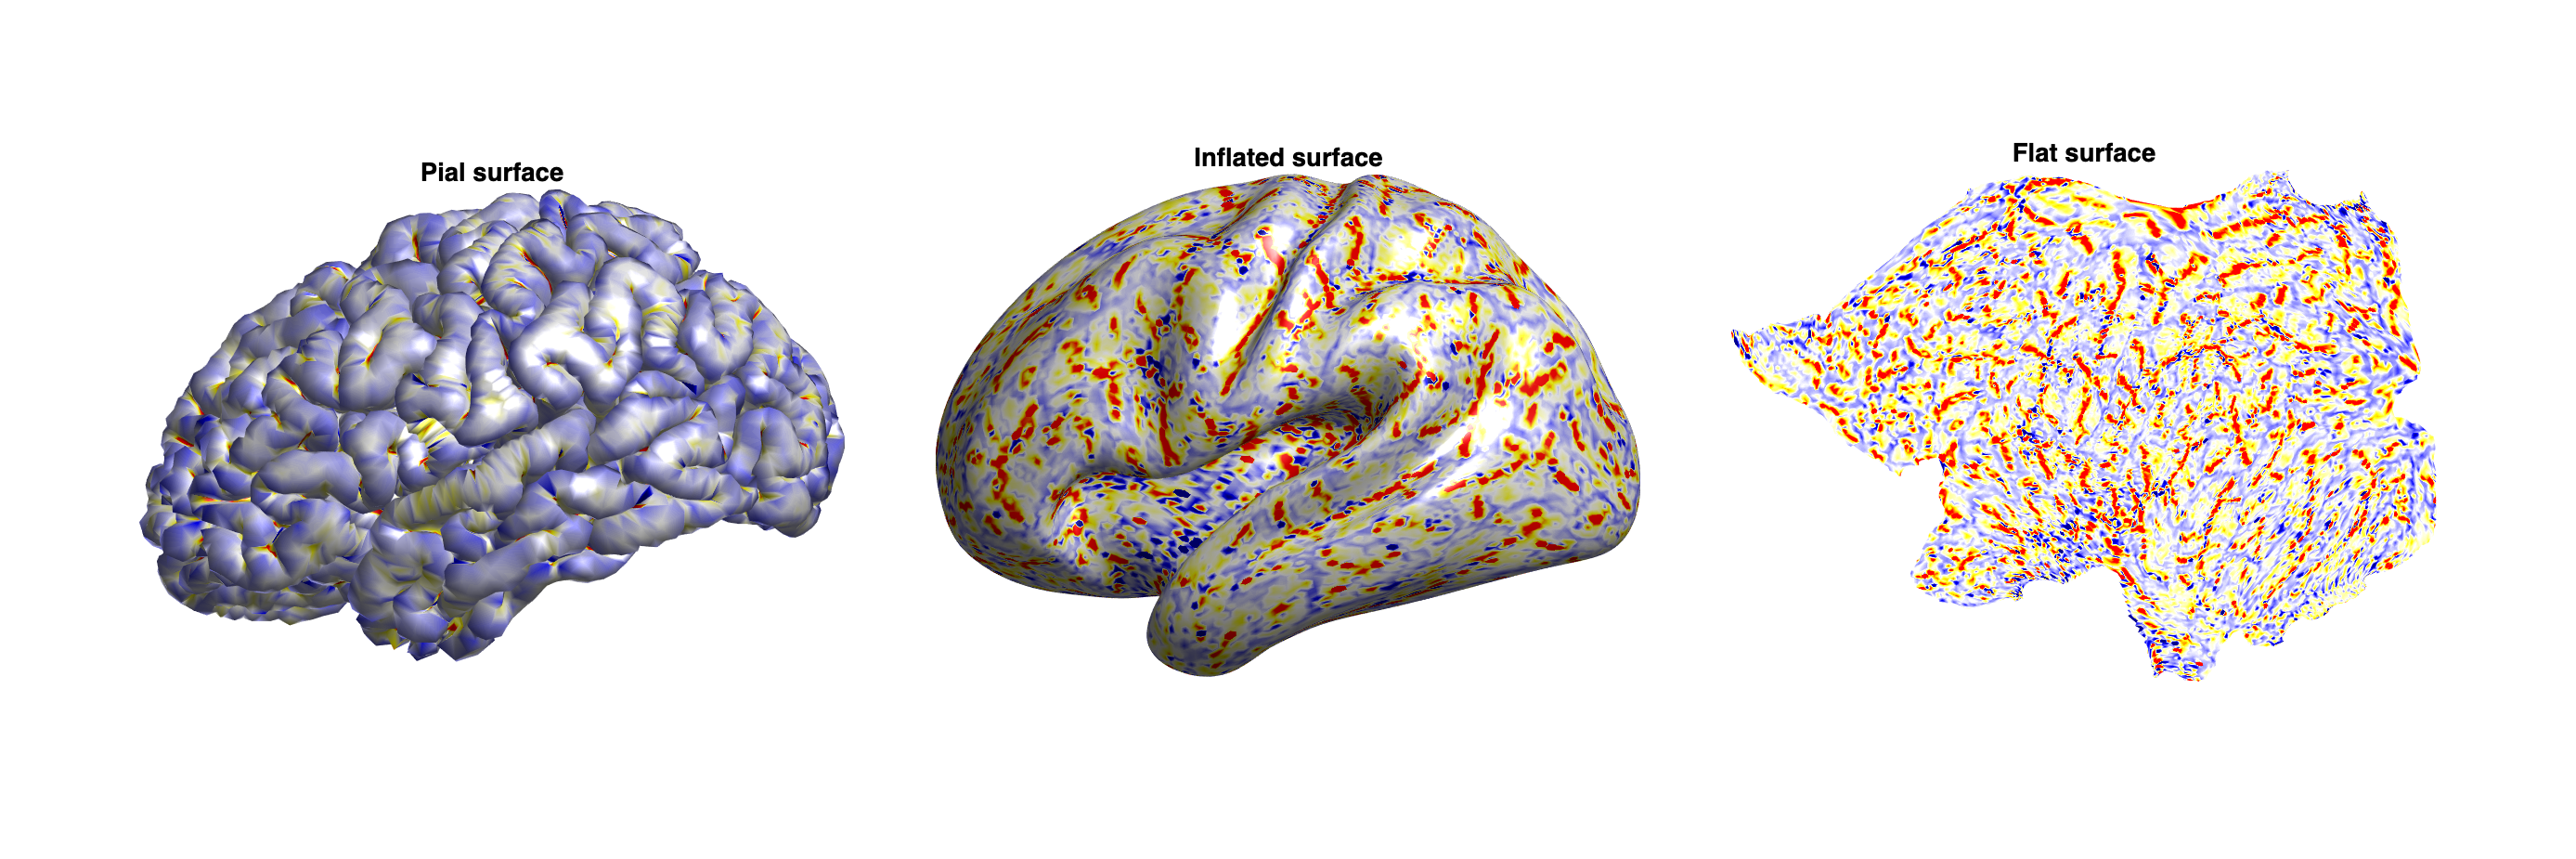

h_mcL = curvature_mean_centering(pialL, curvaturesL.mean);

figure('Position',[100 100 1800 600]);
tiledlayout(1,3,'TileSpacing','compact','Padding','compact');

nexttile;
figure_trimesh(pialL, h_mcL, 'rywb');
view([-90 0]); clim([-0.5 0.5]); camlight;
title('Pial surface');

nexttile;
figure_trimesh(inflatL, h_mcL, 'rywb');
view([-90 0]); clim([-0.5 0.5]); camlight;
title('Inflated surface');

nexttile;
figure_trimesh(flatL, h_mcL, 'rywb');
view(2); clim([-0.5 0.5]);
title('Flat surface');

## Screened Poisson model

We solve the screened Poisson equation on the cortical surface,


$$(\mathcal{L}+\lambda I)u=h,$$


to obtain the scalar folding potential $u$. Using finite-element discretization on the triangular cortical mesh, the equation becomes


$$({\bf L}+\lambda{\bf A})u={\bf A}h,$$


where ${\bf L}$ is the finite-element stiffness matrix representing the Laplace--Beltrami operator and ${\bf A}$ is the mass matrix representing surface area. The finite-element construction follows the cortical surface formulation described in Chung et al. (2003).

Without mean-ceterning, the equation breaks down when $\lambda=0$. The regularization parameter $\lambda>0$ removes the additive-constant ambiguity of the ordinary Poisson equation and controls the spatial scale of the solution. Here we use $\lambda=0.1$. The resulting flow field is defined by the negative surface gradient 


$$J=-\nabla u$$


and displayed as green arrows.

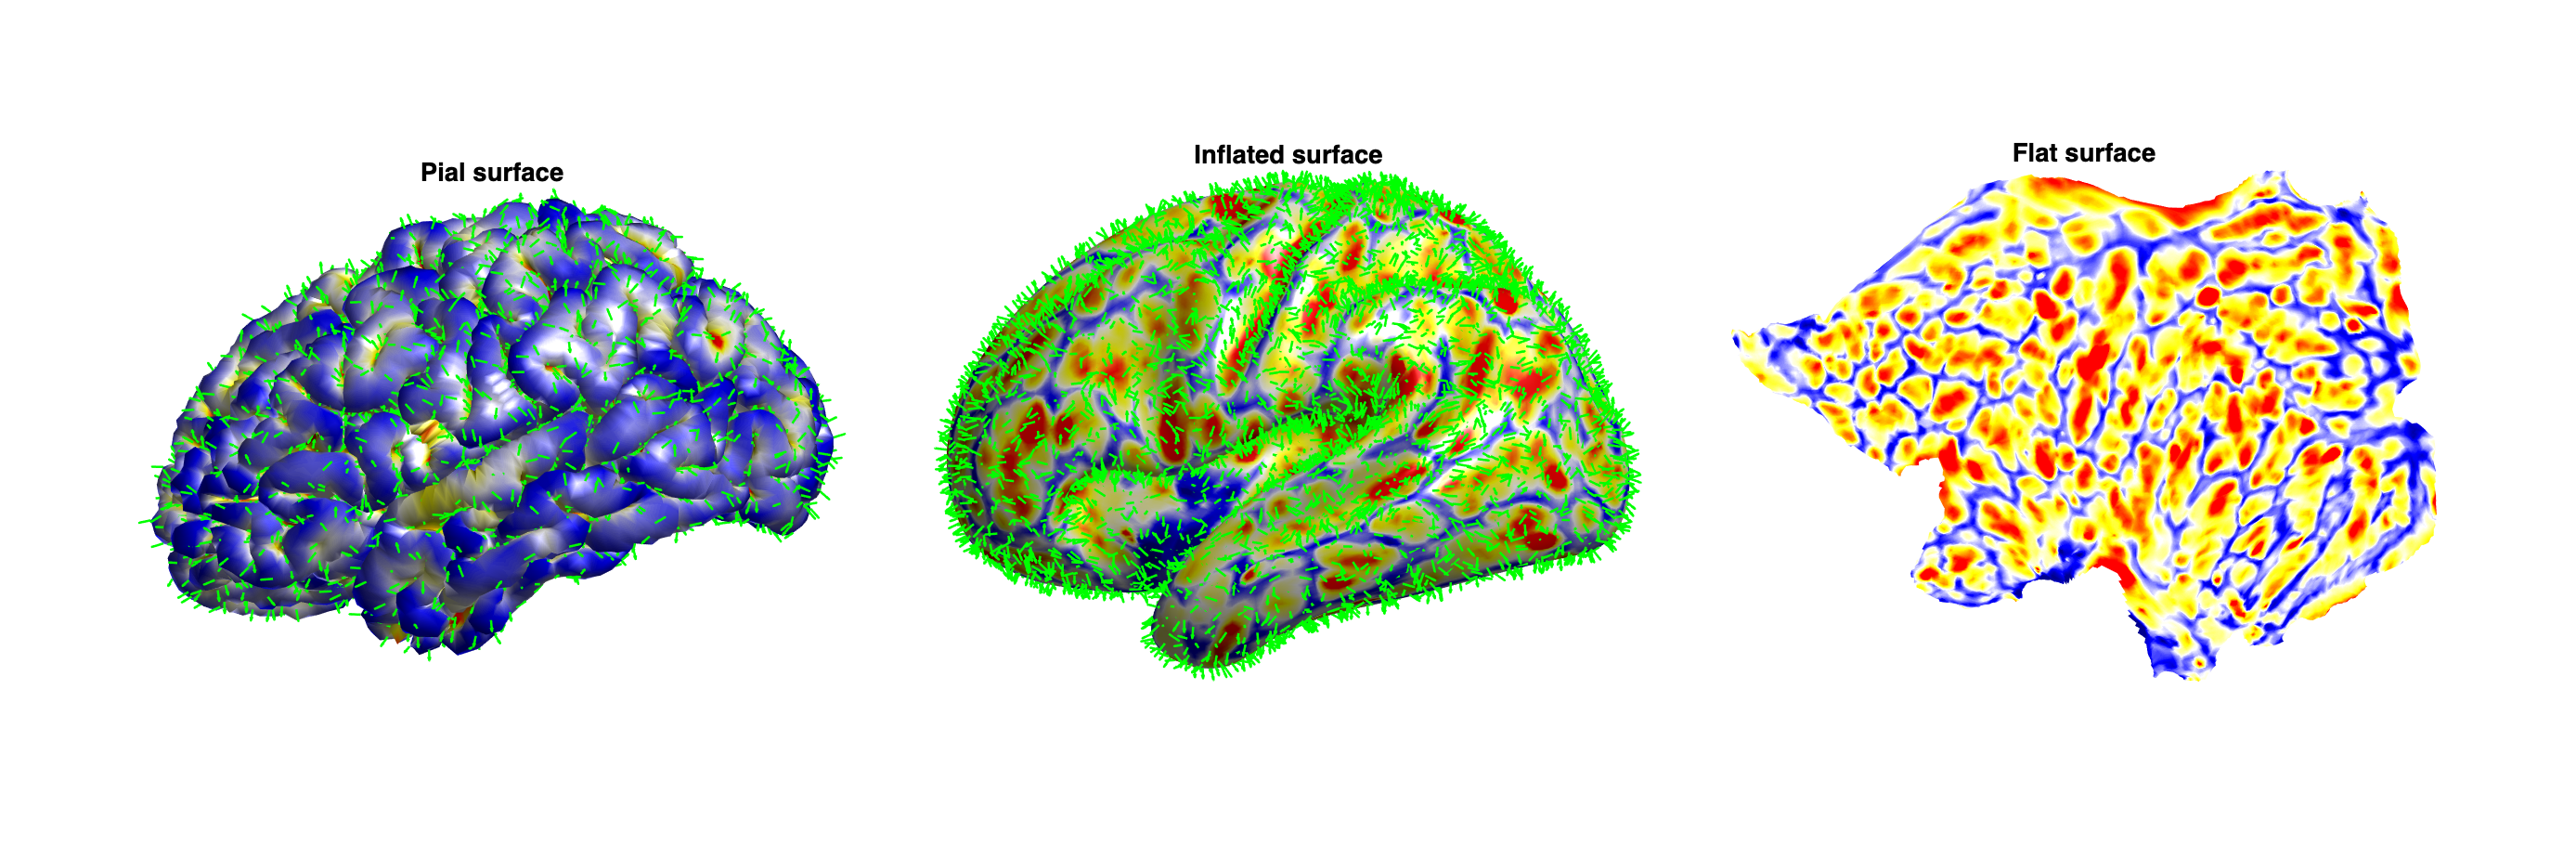

h_mcL       = curvature_mean_centering(pialL, curvaturesL.mean);
figure('Position',[100 100 1800 600]);
tiledlayout(1,3,'TileSpacing','compact','Padding','compact');

nexttile;
figure_trimesh(pialL, uL, 'rywb');
view([-90 0]); clim([-0.5 0.5]); camlight;
title('Pial surface');
hold on; flux_to_display(pialL, JfL, 5, 3, 'vertex');

nexttile;
figure_trimesh(inflatL, uL, 'rywb');
view([-90 0]); clim([-0.5 0.5]); camlight;
title('Inflated surface');
hold on; flux_to_display(inflatL, JfL, 5, 3, 'vertex');

nexttile;
figure_trimesh(flatL, uL, 'rywb');
view(2); clim([-0.5 0.5]);
title('Flat surface');

## Problems

**1. Viaulizing vector field over changed mesh topology. **The pial and inflated cortical surfaces have the same number of vertices and faces, whereas the flattened surface has the same number of vertices but fewer triangular faces:

pialL

pialL = struct with fields:
       faces: [64980×3 int32]
         mat: [4×4 double]
    vertices: [32492×3 single]


inflatL

inflatL = struct with fields:
       faces: [64980×3 int32]
         mat: [4×4 double]
    vertices: [32492×3 single]


flatL

flatL = struct with fields:
       faces: [59013×3 int32]
         mat: [4×4 double]
    vertices: [32492×3 single]


Consequently, directly displaying the flex field  on the flattened surface` flatL `using `flux_to_display.m` fails because the number and indexing of faces are no longer identical. Modify `flux_to_display.m` so that the flow field can be correctly visualized on a surface .

**2. Poisson mean-zero condition. **The ordinary Poisson equation on a closed surface,


$$Lu=h$$


requires the forcing field $h$ to have zero area-weighted mean. Otherwise, there is no solution. Numerically verify and justify why the zero-mean condition is needed.

**3. Poisson flow on a surface. **Trace a path by following the Poisson flux field $J=-\nabla u.$ Starting from a selected cortical vertex, compute and display the resulting Poisson flow path on the cortical surface. Then display the corresponding path on the flattened surface using vertexwise correspondence. Explain how the path relates to the Poisson potential $u$ and the direction of its gradient. How you measure distance along the Poisson flow. 

**4. Geodesic path on a surface.** Given two vertices on the cortical surface, determine the geodesic path connecting them. The geodesic is the shortest path between the two vertices measured along the cortical surface. Display the geodesic path on the cortical surface and its corresponding path on the flattened surface.

5. **Geodesic Path vs. Poisson Flow Path. **Are geoetdic path and poisson flow path identical? Explain the geometric difference between a shortest geodesic path and a path generated by following the Poisson flux field.